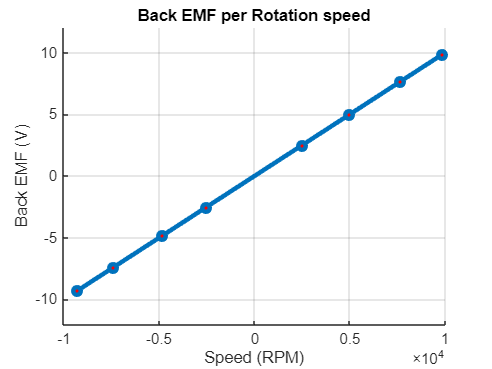

% Back EMF per Rotation speed
Kv = 1000;
rpm = [-9282, -7398, -4842, -2520, 2496, 5004, 7644, 9852];
bemf = zeros(1, length(rpm)); % Preallocate the bemf array
for i = 1:length(rpm) % Adjust indexing to start at 1
    bemf(i) = rpm(i) / Kv;
end
% Create the figure and plot the data
figure;
hold on;
%load("dataV");
plot(rpm, bemf,'-o','MarkerSize',5,'MarkerFaceColor',[1 .0 .0],'LineWidth', 3);

% Set axis limits
xlim([-10000 10000]);
ylim([-12 12]);

% Add labels and title
xlabel('Speed (RPM)');
ylabel('Back EMF (V)');
title('Back EMF per Rotation speed');
% Turn on grid lines
grid on;

%}